%Code to model 6DOF primarily using the paper: 
%https://www.researchgate.net/publication/327064480_Experimental_and_numerical_study_of_chaff_cloud_kinetic_performance_under_the_impact_of_high_speed_airflow
%Completed by BS, JM and AK
clear;

%initialising of parameters (ie angles, coefficients)
theta = 1.0; %pitch angle (radians)
psi_s = 1.1; %yaw? angle (radians)
zeta = 1.2 % (radians)

zeta = 1.2000

psi = 1.3 %(radians)

psi = 1.3000

%nu = 1.0% (radians)

%unit vectors defined
n_d = [(-sin(zeta)*cos(psi)), (cos(zeta)),  (sin(zeta)*sin(psi))] %unit vector of

n_d =    -0.2493    0.3624    0.8981


n_v = [(cos(theta)*cos(psi_s)), sin(theta), (-cos(theta)*sin(psi_s))] %unit vector of velocity 

n_v =     0.2451    0.8415   -0.4815


n_y = [cross(n_v,(cross(n_v,n_d)*dot(n_v,n_d)))/norm(cross(n_v,(cross(n_v,n_d)*dot(n_v,n_d))))] %unit vector of lift 

n_y =    -0.2068    0.5306    0.8220




%variables for kinematics found from unit vectors
gamma_s = -asin((((n_v(3)*n_y(1))-(n_v(1)*n_y(3)))*n_y(2))/(sqrt(((n_v(1))^2)+(n_v(3))^2)*abs(n_y(2))))% roll angle (radians)

gamma_s = 0.1897

%constants 

m - Mass of chaff fibre (grams)

rho - Atmospheric density (assumed constant kg/m^3)

aOne - Distance Impact Factor

fValue - Proportionality constant

dt - Time step value (seconds)

maxTime - Time simulation runs for (seconds)

numberOfChaff - Number of Chaff Fibres

sizeOfChaff - Size of Chaff in output graph

V - initial velocity of chaff

radius - Radius of sphere of chaff

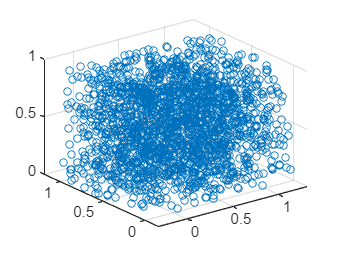

m = 0.05; %mass of chaff (g)
g = 9.81; %accleration due to gravity (ms^2)
rho = 7;  %atmospheric density (assumed constant)
aOne=3;
fValue=0.6;
dt=0.1;
maxTime = 0;
numberOfChaff = 2090;
sizeOfChaff = 20;
V = 0; %chaff velocity 
radius=0;
S = 4*pi*(radius)^2;%area of chaff (m^2) %want to treat like a sphere
 

kinematic_equations(gamma_s,aOne,fValue,0.52,0.82,dt,maxTime,m,g,numberOfChaff,rho,S,sizeOfChaff,V)

function kinematic_equations(gamma_s,aOne,fValue,cXPrime,cYPrime,dt,maxTime,m,g,numberOfChaff,rho,S,sizeOfChaff,V)
      [cX,cY] = calculateAerodynamicInterferenceImpactFactors(aOne,fValue,cXPrime,cYPrime);
      X = 0.5*cX*rho*(V^2)*S;
      Y = 0.5*cY*rho*(V^2)*S;
      theta = pi;
      xValues=[];
      yValues=[];
      zValues=[];
      PsiS = pi;
for i = 1:1:numberOfChaff
    xValueCurrent = rand();
    yValueCurrent = rand();
    zValueCurrent = rand();
    for t = 0.0:dt:maxTime
        dV = ((-X - m*g*sin(theta))/m)*dt;
        dTheta = ((Y*cos(gamma_s) - m*g*cos(theta))/m*V)*dt;
        dPsiS = ((-Y*sin(gamma_s))/m*V*cos(theta))*dt;
        V = V+dV;
        theta = theta + dTheta;
        PsiS = PsiS + dPsiS;
        dX = V*cos(theta)*cos(PsiS)*dt;
        dY = V*sin(theta)*dt;
        dZ = -V*cos(theta)*sin(PsiS)*dt;
        xValueCurrent = xValueCurrent + dX;
        yValueCurrent = yValueCurrent + dY;
        zValueCurrent = zValueCurrent + dZ;
    end
    xValues = [xValues, xValueCurrent];
    yValues = [yValues, yValueCurrent];
    zValues = [zValues, zValueCurrent];
end
%xValues
%yValues
%zValues
figure;
hold on;
grid on;
scatter3(xValues,yValues,zValues,sizeOfChaff);
view(3);
hold off;
end

function [cX,cY] = calculateAerodynamicInterferenceImpactFactors(aOne,fValue,cXPrime,cYPrime);
cX = cXPrime*(1-aOne);
cY = cYPrime*fValue*(1-aOne);
end
